## Initial Conditions

Environmental

clf;
clear;
rho_air = 1.225; % air density [kg/m3]
mu_air = 1.81*10^(-5); % kinematic Viscosity
W_speed_kn = [2.5; 5; 10; 15; 20]; % wind speed [kn]

Sail

S_apsect_ration = 2.7;
S_span = 2.7; % sail height [m]
S_avg_ch = 1; % average chord of sail [m]
S_area = S_span*S_avg_ch; % design sail area [m2]
fprintf('Sail area: %g m2',S_area)

Sail area: 2.7 m2

S_alpha = 9; % sail angle of attack [deg]
fprintf('Sail angle of attack: %g deg',S_alpha)

Sail angle of attack: 9 deg

S_mass = 10; % sail mass [kg]
fprintf('Sail mass: %g kg',S_mass)

Sail mass: 10 kg

S_mast_pos = 0.25; % mast position in terms of avg_ch ratio

Hull

Assumed resistance curve:

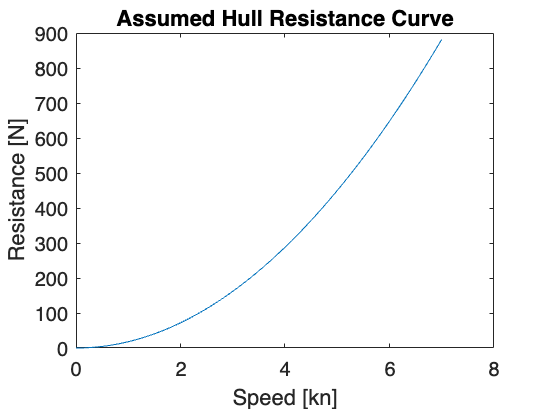

H_par = 18; % hull drag parameter
hull_speeds_pre=0:0.01:7;
hull_resistance_pre=H_par.*hull_speeds_pre.^2;
figure;
plot(hull_speeds_pre, hull_resistance_pre)
title('Assumed Hull Resistance Curve');
xlabel('Speed [kn]');
ylabel('Resistance [N]');

H_speed_kn = 0.01; % initial guess [kn]
H_speed = H_speed_kn/1.94384; % [m/s]
H_heel = deg2rad(0.1); % initial guess heel angle [rad]
H_heading_deg = 45:1:180; % heading relative to true wind [deg]
H_heading_deg(size(H_heading_deg,2)) = 179; % modify last value

Keel

K_length = 1; % Keel length [m]
fprintf('Keel length: %g m',K_length)

Keel length: 1 m

K_weight = 70; % Keel weight [kg]
fprintf('Keel weight: %g kg',K_weight)

Keel weight: 70 kg

%Import Airfoil Data
M = csvread("xf-naca0018-il-Re-500k-200k-100k-Main.csv",1,0);

## Where is the worst heel angle?

Iterating through headdings to find worst heeling angle, at highwst wind speed

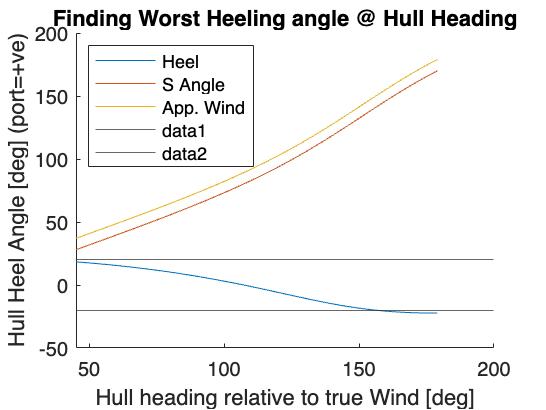

W_speed = W_speed_kn(5)/1.94384;
sailMedium = SailMedium(rho_air, mu_air, M, W_speed, S_area, S_avg_ch, S_alpha, S_span, S_mass);

for k = 1:size(H_heading_deg,2)

    H_heading=deg2rad(H_heading_deg(k));

    S_area_M=S_area;
    difference=1;
    while (difference > 0.0001) 
        % Compute
        [W_app_angle] = getApparentWind(W_speed, H_speed, H_heading);
        [S_thrust,S_torque,S_angle]=sailMedium.computeSailState(W_app_angle, H_heel);
        [H_heel]=keel(S_torque, K_length, K_weight);
        [H_speed]=hull(S_thrust, H_par);
        
        % Rectify Area
        old_S_area_M=S_area_M;
        S_area_M=S_area*cos(H_heel);

        % difference
        difference=abs(old_S_area_M-S_area_M);
    end
    heel_at_heading(k)=rad2deg(H_heel);
    S_torque_at_heading(k)=S_torque;
    S_angle_at_heading(k)=rad2deg(S_angle);
    apparent_wind_angle_at_heading(k)=rad2deg(W_app_angle);
end

% plotting heel angle
figure;
hold on;
plot(H_heading_deg, heel_at_heading)
%plot(H_heading_deg, S_torque_at_heading)
plot(H_heading_deg, S_angle_at_heading)
plot(H_heading_deg, apparent_wind_angle_at_heading)
legend('Heel', 'S Angle', 'App. Wind', 'Location','northwest')

yline(20);
yline(-20);
title('Finding Worst Heeling angle @ Hull Heading')
xlabel('Hull heading relative to true Wind [deg]')
ylabel('Hull Heel Angle [deg] (port=+ve)')

Finding worst heeling angle heading

maximum = max(heel_at_heading);
minimum = min(heel_at_heading);
if (abs(minimum) > maximum)
    to_find=minimum;
else
    to_find=maximum;
end
[~,y]=find(heel_at_heading==to_find);
fprintf('Worst Heeling Angle: %g deg',to_find)

Worst Heeling Angle: -22.3007 deg

fprintf('Worst Heeling Angle @ Heading: %g deg',H_heading_deg(1,y))

Worst Heeling Angle @ Heading: 179 deg

## Keel Study - Length

Here we investigate the variance of keel parameters on the performance. We choose a heading of 126deg (20deg of heel in the previous plot), and max wind speed (20kn)

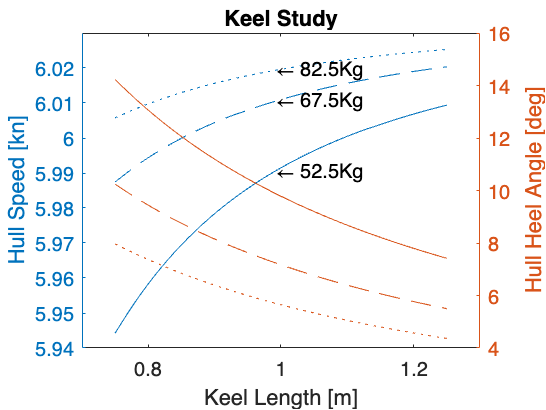

% modifying keel values
K_weightArr = (K_weight-K_weight*0.25):15:(K_weight+K_weight*0.25);
K_lengthArr = (K_length-K_length*0.25):0.01:(K_length+K_length*0.25);
% setting environmental const
W_speed = W_speed_kn(5)/1.94384;
H_heading=deg2rad(90);

for j = 1:size(K_weightArr,2)
    for k = 1:size(K_lengthArr,2)
        S_area_M=S_area;
        difference=1;
        while (difference > 0.0001) 
            % Compute
            [W_app_angle] = getApparentWind(W_speed, H_speed, H_heading);
            [S_thrust,S_torque,S_angle]=sailMedium.computeSailState(W_app_angle, H_heel);
            [H_heel]=keel(S_torque, K_lengthArr(k), K_weightArr(j));
            [H_speed]=hull(S_thrust, H_par);
            
            % Rectify Area
            old_S_area_M=S_area_M;
            S_area_M=S_area*cos(H_heel);
    
            % difference
            difference=abs(old_S_area_M-S_area_M);
        end
        H_speeds_at_keel(j,k)=H_speed*1.94384;
        H_heel_deg_at_keel(j,k)=rad2deg(H_heel);
    end 
end

figure;
% find half of domain
half_of_x_domain=fix(size(K_lengthArr,2)/2);
yyaxis left
plot(K_lengthArr, H_speeds_at_keel(1,:));
ylabel('Hull Speed [kn]')
text(K_lengthArr(1,half_of_x_domain),H_speeds_at_keel(1,half_of_x_domain),'\leftarrow' + string(K_weightArr(1)) + 'Kg')
yyaxis right
plot(K_lengthArr, H_heel_deg_at_keel(1,:));
ylabel('Hull Heel Angle [deg]')
title('Keel Study')
xlabel('Keel Length [m]')
hold on
for w = 2:size(H_speeds_at_keel,1)
    yyaxis left
    plot(K_lengthArr, H_speeds_at_keel(w,:));
    text(K_lengthArr(1,half_of_x_domain),H_speeds_at_keel(w,half_of_x_domain),'\leftarrow' + string(K_weightArr(w)) + 'Kg')
    yyaxis right
    plot(K_lengthArr, H_heel_deg_at_keel(w,:));
end
hold off

## Polar Plot

Interation to find boat speed based on wind speed and heading relative to wind

% Augmenting Wind Speed
for w = 1:size(W_speed_kn,1)

    W_speed = W_speed_kn(w)/1.94384;
    
    % Heading Respect to True Wind
    for k = 1:size(H_heading_deg,2)

        H_heading=deg2rad(H_heading_deg(k));

        S_area_M=S_area;
        difference=1;
        i=0;
        while (difference > 0.0001) 
            i=i+1;
            % Compute
            [W_app_angle] = getApparentWind(W_speed, H_speed, H_heading);
            [S_thrust,S_torque,S_angle]=sailMedium.computeSailState(W_app_angle, H_heel);
            [H_heel]=keel(S_torque, K_length, K_weight);
            [H_speed]=hull(S_thrust, H_par);
            
            % Rectify Area
            old_S_area_M=S_area_M;
            S_area_M=S_area*cos(H_heel);
    
            % difference
            difference=abs(old_S_area_M-S_area_M);
        end
        speed_polar(k,w) = H_speed*1.94384;
    end
end
% plotting polar speed
figure;
color_array=['c'; 'b'; 'g'; 'y'; 'r'];
label_array=num2str(W_speed_kn);
label_array=label_array + "kn";
speed_polar_temp=transpose(speed_polar(:,1));
H_heading_temp=deg2rad(H_heading_deg);
polarplot(H_heading_temp,speed_polar_temp,color_array(1))
title('Hull Speed [kn] @ Hull Headings [deg] and Wind Speeds [kn]');
text(H_heading_deg(1),speed_polar(1,1),label_array(1,:));
hold on;
for w = 2:size(speed_polar,2)
    speed_polar_temp=transpose(speed_polar(:,w));
    H_heading_temp=deg2rad(H_heading_deg);
    polarplot(H_heading_temp,speed_polar_temp,color_array(w))
    text(H_heading_deg(1),speed_polar(1,w),label_array(w,:));
end
maximum = max(max(speed_polar_temp));
[x,y]=find(speed_polar==maximum);
fprintf('Optimal Sailing Heading: %g deg',H_heading_deg(1,x))